# Tutorial 10 -- Mapping

## The Mapping Toolbox

Matlab's Mapping Toolbox contains all sorts of functions for mapping geospatial data. Here is a link to the documentation: [https://www.mathworks.com/help/map/getting-started-with-mapping-toolbox.html?s_tid=CRUX_lftnav](https://www.mathworks.com/help/map/getting-started-with-mapping-toolbox.html?s_tid=CRUX_lftnav) 

#### worldmap & geoshow

Let's start by visualizing the world with the 'worldmap' function.

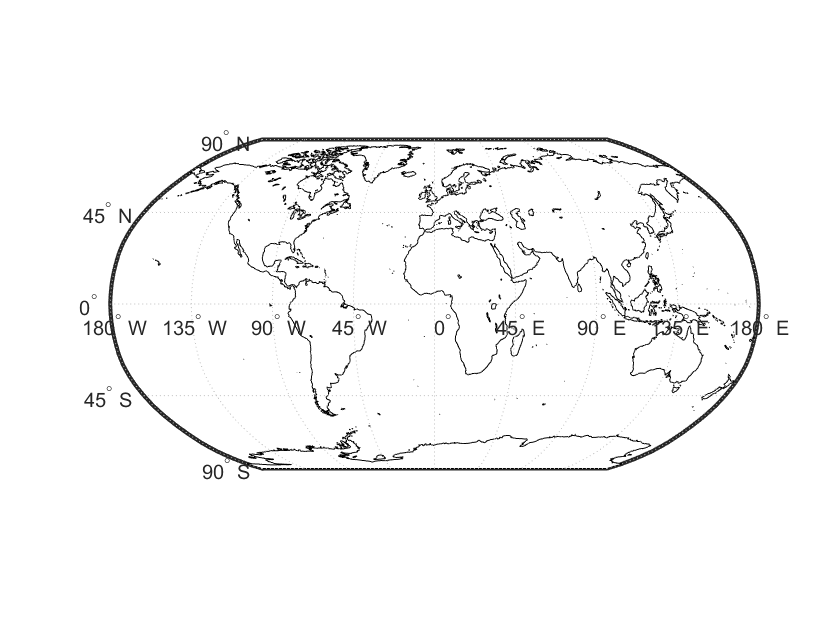

figure;
ax = worldmap('World');
set(ax,'Visible','off')
geoshow('landareas.shp','DefaultFaceColor','white','DefaultEdgeColor','black')

I don't care for the bounding box or axis labels. Let's remove all of that information.

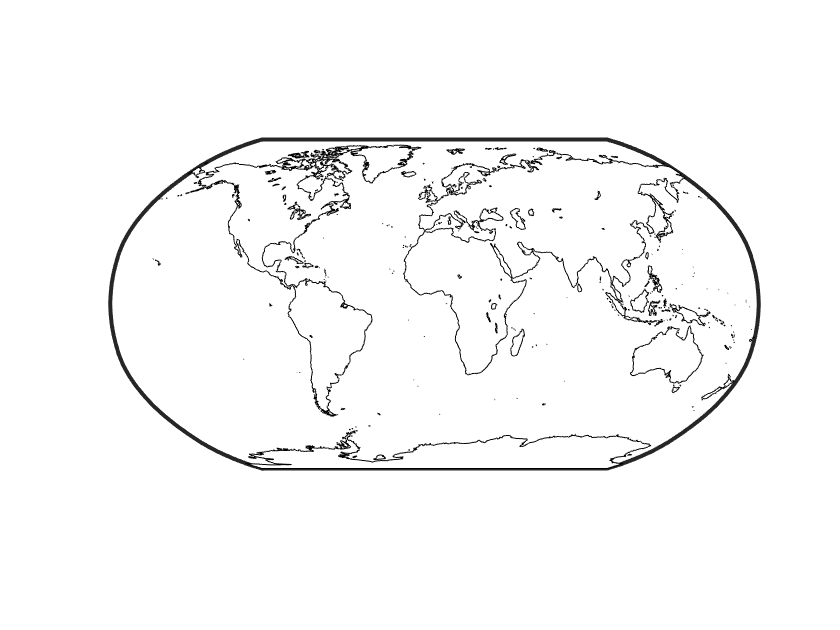

framem on
gridm off
mlabel off
plabel off

#### wmsfind (webmaps)

It does the job, but it's a little boring. Let's add some color by using a web map. NASA's blue marble: Next Generation project seems like a good place to start. [https://earthobservatory.nasa.gov/features/BlueMarble/BlueMarble_history.php](https://earthobservatory.nasa.gov/features/BlueMarble/BlueMarble_history.php) 

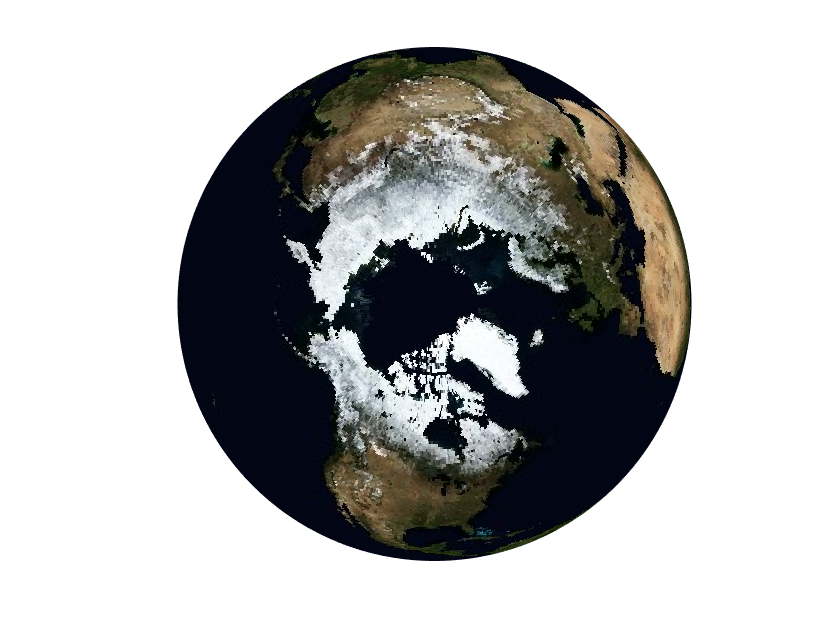

nasa = wmsfind('NASA','SearchField','serverurl');
layer = refine(nasa,'bluemarbleng', ...
    'SearchFields','layername', ...
    'MatchType', 'exact');
[A,R] = wmsread(layer(1));
figure;
axesm globe
axis off
geoshow(A,R)

#### webmap

Let's conclude this section by looking at webmaps. Here is a list of choices for base webmaps: [https://www.mathworks.com/help/map/ref/webmap.html](https://www.mathworks.com/help/map/ref/webmap.html) 

webmap 'National Geographic Map'
%webmap 'USGS Imagery'

## Music Programs in Texas

If your arts objects contain coordinates for latitude and longitude (e.g., locations of theatre houses, concert halls, compositions by Mozart, etc.), you can visualize those locations on a map. A previous student was interested in the location of music programs in Texas, so she created a list of lat.,long. coordinates for a few programs. Let's look at them.

#### usamap -- states

'usamap' is a function that creates a visualization of any state in the USA, or the entire country itself. We'll start with Texas.

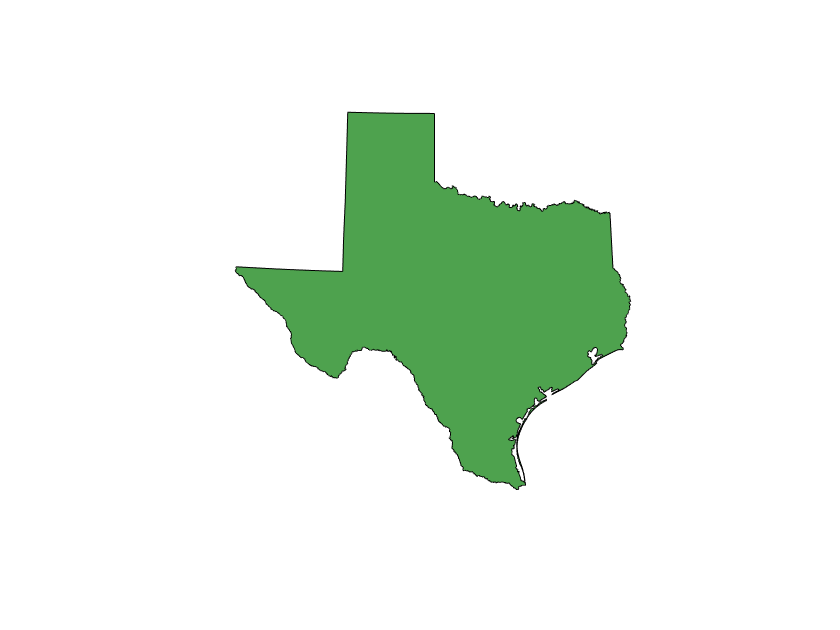

figure;
ax = usamap('Texas');
set(ax,'Visible','off')
shape = shaperead('usastatehi','UseGeoCoords', true,'Selector',{@(name) strcmpi(name,'Texas'),'Name'});
geoshow(shape,'FaceColor',[78/255 162/255 78/255])
framem off
gridm off
mlabel off
plabel off

#### scatterm & textm

Now let's label three high schools on the map: Lamar, Little Elm, and Alpine. 'scatterm' creates the dots, and 'textm' creates the labels.

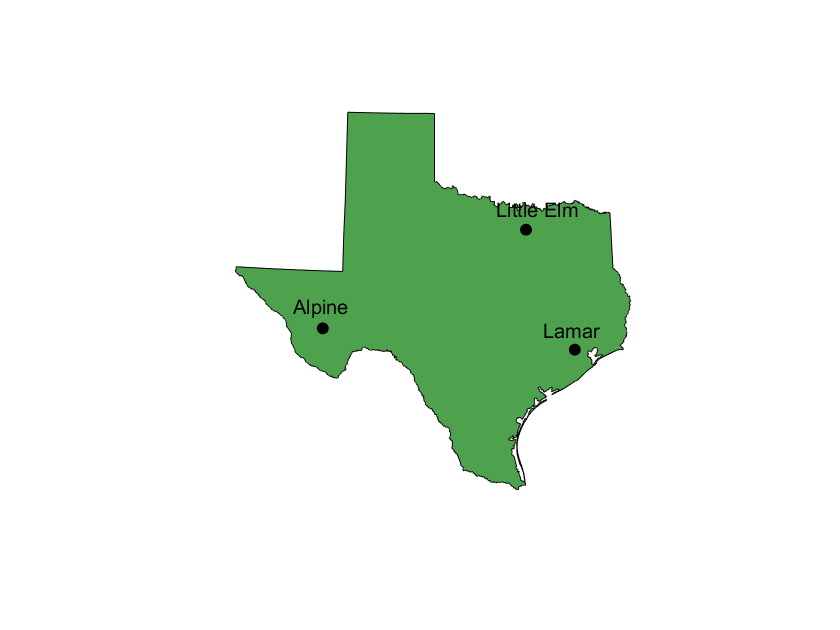

high = {'Lamar' 'Little Elm' 'Alpine'};
high_latlon = [29.7405 -95.4261; 33.1813 -96.9069; 30.3720 -103.6657];
c = repmat([0 0 0],size(high_latlon,1),1);
scatterm(high_latlon(:,1),high_latlon(:,2),[],c,'filled')
textm(high_latlon(:,1)+.6,high_latlon(:,2)-1,high)

Now let's do the same for three universities. We'll color those dots blue to differentiate them from the high schools.

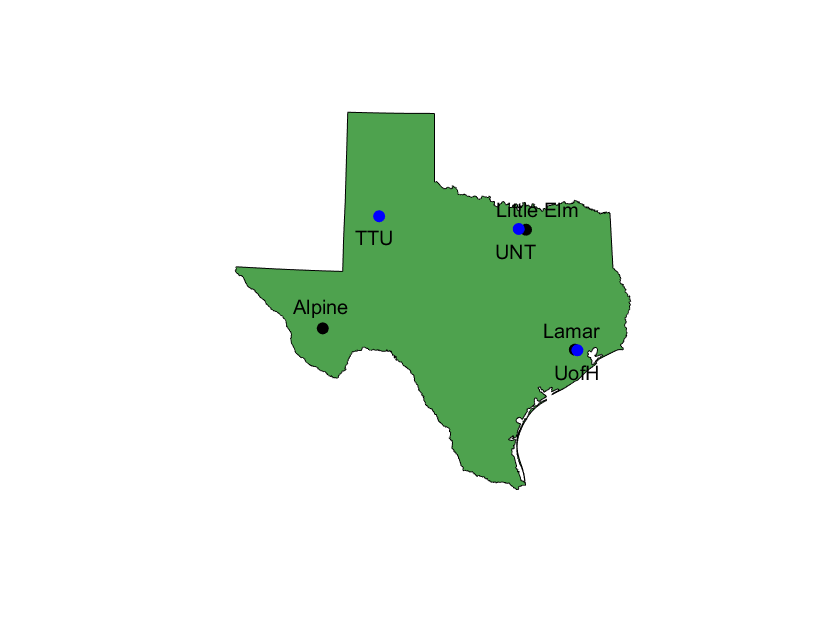

uni = {'TTU' 'UNT' 'UofH'};
uni_latlon = [33.5843 -101.8783; 33.2075 -97.1526; 29.7199 -95.3422];
cc = repmat([0 0 1],size(uni_latlon,1),1);
scatterm(uni_latlon(:,1),uni_latlon(:,2),[],cc,'filled')
textm(uni_latlon(:,1)-.6,uni_latlon(:,2)-.8,uni)

## RadioGarden

#### api

What about if we want to map many locations across the planet? Let's grab the coordinates for every radio station in the Radio Garden API!

loc = webread('http://radio.garden/api/ara/content/places');
loc = loc.data.list;
loc = struct2table(loc);
loc(1:5,:)

ans = 5×7 table
         id             geo                           url                      size    boost             title              country  
    ____________    ____________    _______________________________________    ____    _____    _______________________    __________

    {'cGtBAqae'}    {2×1 double}    {'/visit/jalpa/cGtBAqae'              }      1     false    {'Jalpa'              }    {'Mexico'}
    {'-GDYth6_'}    {2×1 double}    {'/visit/izucar-de-matamoros/-GDYth6_'}      1     false    {'Izúcar de Matamoros'}    {'Mexico'}
    {'wtNFAzwK'}    {2×1 double}    {'/visit/athens/wtNFAzwK'             }    148     false    {'Athens'             }    {'Greece'}
    {'nkeutQ57'}    {2×1 double}    {'/visit/belgrade/nkeutQ57'           }

size(loc,1) % How many locations does Radio Garden feature?

ans = 11758

Radio Garden contains radio stations from 11,758 locations on the planet! Let's visualize them. To do that, we need to clean up the geo coordinates a bit.

geo = loc.geo;
for i = 1:length(geo)
    geo1(i,:) = [geo{i}]';
end
geo1(1:10,:)

ans =  -102.9779   21.6374
  -98.4678   18.5991
   23.7294   37.9839
   20.4489   44.7866
  -99.6760   18.8391
   12.4964   41.9028
  -70.9000  -33.7465
  -71.6053  -33.5923
  -70.9607  -31.7825
  -98.9080   19.3091


#### geobasemap

Now let's create the map. I'll use the 'streets-dark' basemap. 

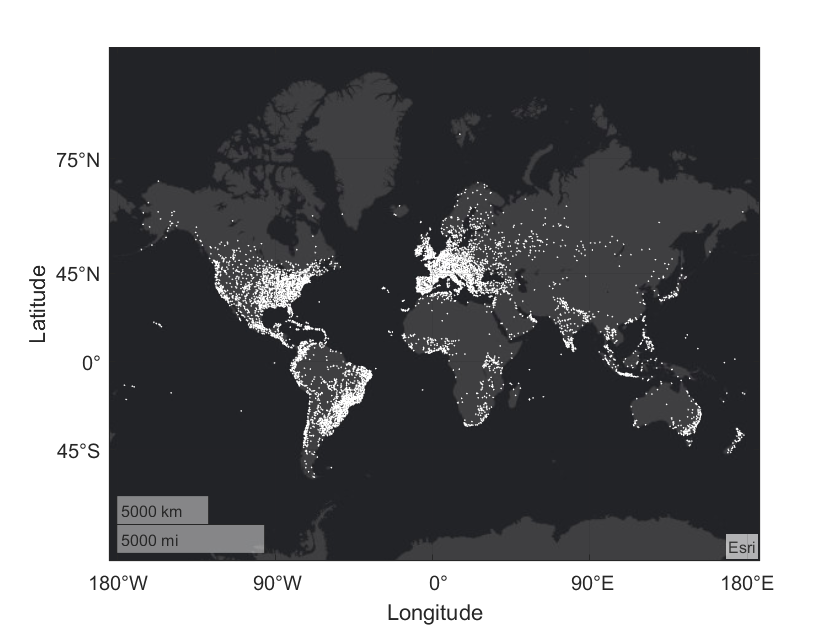

figure;
gx = geoaxes;
S = geoscatter(gx,geo1(:,2),geo1(:,1),1,'white','filled');
geobasemap streets-dark

The 'size' column in the RadioGarden table demonstrates that some locations feature more radio stations than others. The size of each dot on the map could reflect the number of stations at that location! 

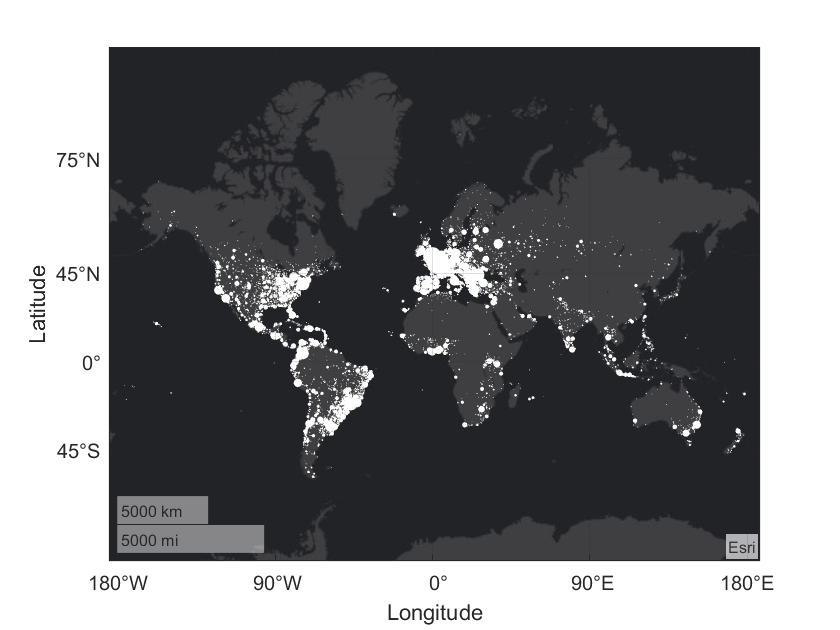

sz = loc.size; 
figure;
gx = geoaxes;
S = geoscatter(gx,geo1(:,2),geo1(:,1),sz/5,'white','filled');
geobasemap streets-dark